close all
clear
clc

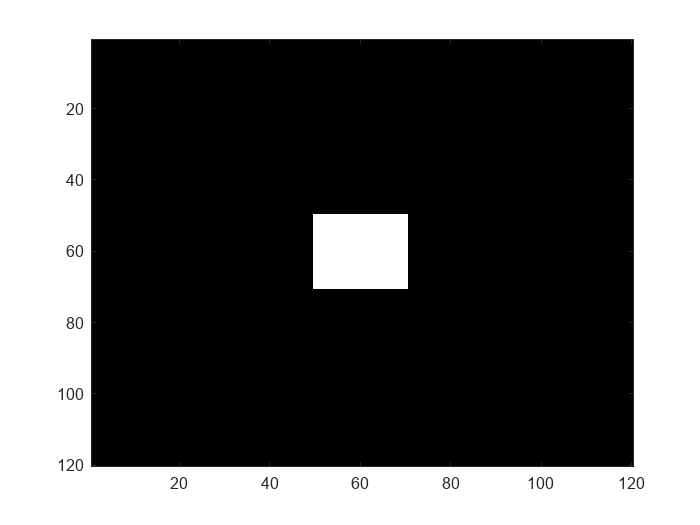

A = zeros(120, 120, 3);
A(size(A)/2-10:size(A)/2+10, size(A)/2-10:size(A)/2+10, :) = 10;
imagesc(A);

x = 50; 
y = 60; 
z = 1;



N = 5; %numero di formiche
Ant(1:N) = ant;
init_voxel = [x, y, z];
neighbours = find_first_neigh(A, x, y, z);

a = neighbours{1};
b = neighbours{2};
c = neighbours{3};
rng shuffle

for i=1:length(Ant)
Ant(i).x = a(randi(length(a)));
Ant(i).y = b(randi(length(b)));
Ant(i).z = c(randi(length(c)));
end
B = Pheromone_map;
B.A = A;
pheromone_map = B.initialize_matrix();
pheromone = [];
Cell = {0 ; 0};
e_death = 1;
e_reproduction = 1.3;

tic
cycles = 1;
while cycles < 500
    j = 1;
    while j < length(Ant)
        pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 2) = Ant(j).mark_voxel(pheromone_map);
        pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 1) = Ant(j).pheromone_release(A);
        pheromone = [pheromone, Ant(j).pheromone_release(A) - Ant(j).eta];
        Ant(j).energy = Ant(j).update_energy(pheromone(j), sum(pheromone)/numel(pheromone));
        if Ant(j).energy < e_death
            %disp('Morte della formica')
            Ant(j) = [];
            N = N - 1;
        elseif Ant(j).energy > e_reproduction
            %disp('Riproduzione della formica')
            Ant(j).energy = 1.2;
            Daughter_ant = ant;
            next_voxel = Ant(j).evaluate_destination(pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 1), pheromone_map);
            if isempty(next_voxel)==1
                Daughter_ant = [];
            else
                Daughter_ant.x = next_voxel(1);
                Daughter_ant.y = next_voxel(2);
                Daughter_ant.z = next_voxel(3);
                Ant = [Ant, Daughter_ant];
                N = N + 1;
            end
        end
        j = j + 1;
    end
    if N < 1
        break;
    end
    j = 1;
    while j < length(Ant)
        next_voxel = Ant(j).evaluate_destination(pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 1), pheromone_map);
        if isempty(next_voxel) == 1
            %disp('Nessun voxel disponibile, morte della formica')
            Ant(j) = [];
            N = N - 1;
        else
            Ant(j).x = next_voxel(1);
            Ant(j).y = next_voxel(2);
            Ant(j).z = next_voxel(3);
        end
        pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 2) = Ant(j).leave_voxel(pheromone_map);
        j = j + 1;
    end
    if N < 1
        break;
    end
    Cell{1} = [Cell{1}, N];
    Cell{2} = [Cell{2}, cycles];
    cycles = cycles + 1;
end
   

toc

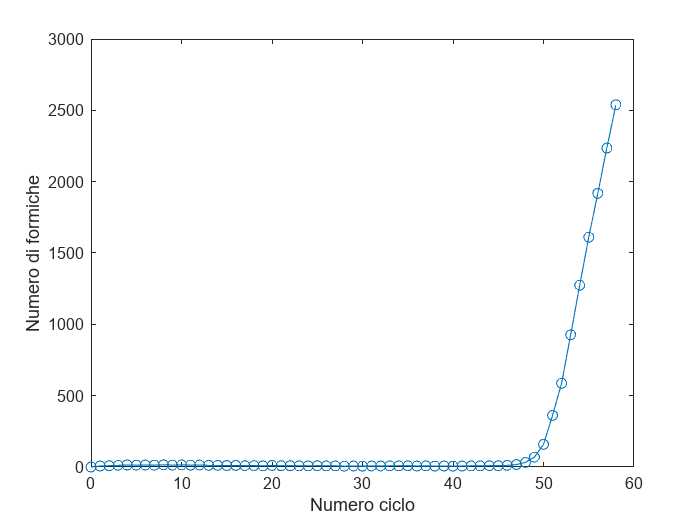

plot(Cell{2, :}, Cell{1, :}, marker = 'o', linestyle = '-')
xlabel('Numero ciclo')
ylabel('Numero di formiche')

Cell{1, :}

ans =      0     7     9    12    14    13    14    13    15    13    15    13    14    12    12    10    11     9    10     8    11     9     9     8     8     9     8     8     6     7     6     7     7     8     8     9     7     8     6     7     6     7     8     8     9     9    12    17    32    69


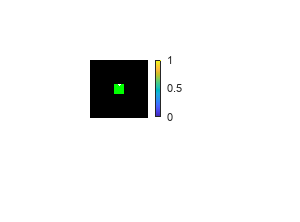

PM = pheromone_map(:, :, :, 1);
imshowpair(A,PM), colorbar;

orthosliceViewer(PM);

